# Ver 3 Network:

- Presynaptic neuron # fixed;

- Boundaries tape back

- LGN: Phase variant

- Adding complex cells

# Tune the network for Paper 2 now

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

% load('NtWk_Archit.mat')
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
% N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_S_HC = 45; n_C_HC = 30; n_I_HC = 31; % per side of HC
N_S = n_S_HC^2 * N_HC^2; % neuron numbers In all
N_C = n_C_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
N_E = N_S+N_C; CplxR = N_C/N_E;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_S = Size_HC/n_S_HC; Size_C = Size_HC/n_C_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnS.X,NnS.Y] = V1Field_Generation(N_HC,1:N_S,'e',n_S_HC,n_I_HC);
[NnC.X,NnC.Y] = V1Field_Generation(N_HC,1:N_C,'e',n_C_HC,n_I_HC);
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');
%NnE.X = [NnS.X,NnC.X]; NnE.Y = [NnS.Y,NnC.Y];

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_S = n_S_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_C = n_C_HC^2 * (N_HC+2)^2; 
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnSex.X,NnSex.Y] = V1Field_Generation(N_HC+2,1:Nex_S,'e',n_S_HC,n_I_HC);
[NnCex.X,NnCex.Y] = V1Field_Generation(N_HC+2,1:Nex_C,'e',n_C_HC,n_I_HC);
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');

Now select complx cells

## Tuning NOW!!!

N_EE = 193; N_EI = 85; %*0.75
N_IE = 844; N_II = 84; %*0.75 Plan A:Original

CplxNEIncr = 253/N_EE; % Was 250 for 071021 simulation
EcplxInd = ismember(1:N_E, N_S+1:N_E); 

N_SS = N_EE * (1-CplxR);            N_SC = N_EE * (CplxR); 
N_CS = N_EE * (1-CplxR)*CplxNEIncr; N_CC = N_EE * (CplxR)*CplxNEIncr;
N_SI = N_EI;                        N_CI = N_EI; 
N_IS = N_IE * (1-CplxR);            N_IC = N_IE * (CplxR); 

## Get a mapping between original and extended spatial indexs

% From original to extended
SMap_Ori2Ext = find(NnSex.X>n_S_HC & NnSex.X<=4*n_S_HC ...
                  & NnSex.Y>n_S_HC & NnSex.Y<=4*n_S_HC);
CMap_Ori2Ext = find(NnCex.X>n_C_HC & NnCex.X<=4*n_C_HC ...
                  & NnCex.Y>n_C_HC & NnCex.Y<=4*n_C_HC);
IMap_Ori2Ext = find(NnIex.X>n_I_HC & NnIex.X<=4*n_I_HC ...
                  & NnIex.Y>n_I_HC & NnIex.Y<=4*n_I_HC);
% from extended back to original: fold
% E
SMap_Ext2Ori = FoldExMap2Ori(NnSex,NnS,SMap_Ori2Ext,N_S,n_S_HC);
CMap_Ext2Ori = FoldExMap2Ori(NnCex,NnC,CMap_Ori2Ext,N_C,n_C_HC);
% I
IMap_Ext2Ori = FoldExMap2Ori(NnIex,NnI,IMap_Ori2Ext,N_I,n_I_HC);
% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary
% EE
C_SS_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...% 
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_EE,SD_E,Dist_LB,1, round(N_SS));

Elapsed time is 8.930864 seconds.


C_SC_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...% 
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_EE,SD_E,Dist_LB,0, round(N_SC));

Elapsed time is 5.375371 seconds.


C_CS_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...% 
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_EE,SD_E,Dist_LB,0, round(N_CS));

Elapsed time is 4.376282 seconds.


C_CC_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...% 
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_EE,SD_E,Dist_LB,1, round(N_CC));

Elapsed time is 2.554678 seconds.


C_EE_Fix_Bd = [C_SS_Fix_Bd, C_SC_Fix_Bd; C_CS_Fix_Bd, C_CC_Fix_Bd];
% EI
C_SI_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...
                                       N_I,NnIex,Size_I, IMap_Ext2Ori, 1:N_I,...
                                       Peak_I,SD_I,Dist_LB,0, round(N_SI));

Elapsed time is 6.018886 seconds.


C_CI_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...
                                       N_I,NnIex,Size_I, IMap_Ext2Ori, 1:N_I,...
                                       Peak_I,SD_I,Dist_LB,0, round(N_CI));

Elapsed time is 2.664539 seconds.


C_EI_Fix_Bd = [C_SI_Fix_Bd; C_CI_Fix_Bd];
% IE
C_IS_Fix_Bd = ConnectionMat_FB_SimCplx(N_I,NnIex,Size_I, IMap_Ori2Ext, 1:N_I,...
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_I,SD_E,Dist_LB,0, round(N_IS));

Elapsed time is 8.511110 seconds.


C_IC_Fix_Bd = ConnectionMat_FB_SimCplx(N_I,NnIex,Size_I, IMap_Ori2Ext, 1:N_I,...
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_I,SD_E,Dist_LB,0, round(N_IC));

Elapsed time is 4.122513 seconds.


C_IE_Fix_Bd = [C_IS_Fix_Bd, C_IC_Fix_Bd];
% II
C_II_Fix_Bd = ConnectionMat_Fix_Boundary(N_I,NnIex,Size_I, IMap_Ori2Ext,...
                                         N_I,NnIex,Size_I, IMap_Ext2Ori,...
                                         Peak_I,SD_I,Dist_LB,1, round(N_II));

Elapsed time is 2.824314 seconds.



CMatAll = struct('C_EE_Fix_Bd',C_EE_Fix_Bd,...
                 'C_EI_Fix_Bd',C_EI_Fix_Bd,...
                 'C_IE_Fix_Bd',C_IE_Fix_Bd,...
                 'C_II_Fix_Bd',C_II_Fix_Bd);


### Checking presyn neurons to boundary neurons. Can jump

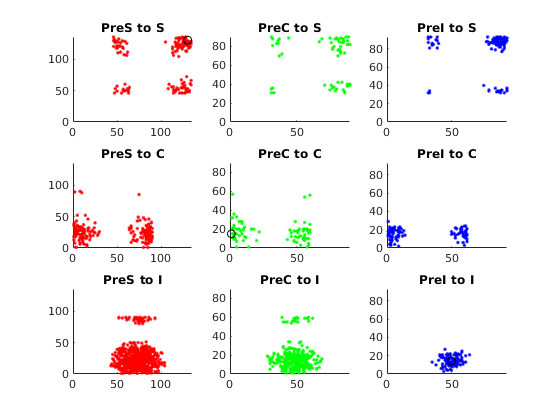

figure
% S cell as post
SX = 130; SY = 130;
SInd = find(NnS.X == SX & NnS.Y == SY);
PreSInd = find(C_SS_Fix_Bd(SInd,:));
PreCInd = find(C_SC_Fix_Bd(SInd,:));
PreIInd = find(C_SI_Fix_Bd(SInd,:));

subplot 331
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
scatter(SX,SY,'kO')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to S')

subplot 332
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to S')

subplot 333
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to S')

% C cell as post
CX = 1; CY = 15;
CInd = find(NnC.X == CX & NnC.Y == CY);
PreSInd = find(C_CS_Fix_Bd(CInd,:));
PreCInd = find(C_CC_Fix_Bd(CInd,:));
PreIInd = find(C_CI_Fix_Bd(CInd,:));

subplot 334
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to C')

subplot 335
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
scatter(CX,CY,'kO')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to C')

subplot 336
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to C')

% I cell as post
IX = 50; IY = 14;
IInd = find(NnI.X == IX & NnI.Y == IY);
PreSInd = find(C_IS_Fix_Bd(IInd,:));
PreCInd = find(C_IC_Fix_Bd(IInd,:));
PreIInd = find(C_II_Fix_Bd(IInd,:));

subplot 337
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to I')

subplot 338
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to I')

subplot 339
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
scatter(IX,IY,'kO')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to I')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.530; 
rI_amb = 0.435; % was 0.5 for for 071021 simulation

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.8;  % was 1.6 for for 071021 simulation
S_II = 0.120; S_IE = S_II*0.153 * 1.6/1.8;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
N_Slgn = 4.75; N_Clgn = 1.25; N_Ilgn = 4.5;

lambda_E = 0.02*[N_Slgn*ones(N_S,1);N_Clgn*ones(N_C,1)]; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.02*N_Ilgn; 

## Network Simulation: BG

%% Network Simulation
T = 1000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.1; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.1; N_IEDly = floor(T_IEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% 
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
% N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
[InEs, InIs] = LargeNW_LoadIniState('Initials_L6.mat', [],N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = sparse(N_I,N_IEDly);
%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

S_Ind = 10000:13000; C_Ind = N_S:N_S+1000;
I_Ind = 3300:4300;
tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEnIEDelay(...
        RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
%         ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
%             ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
%             'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
%             ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
%             'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        %fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        scatterS = find(ismember(E_Sp(:,1),S_Ind));
        scatterC = find(ismember(E_Sp(:,1),C_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,S_Fire_Ind] = ismember(E_Sp(scatterS,1),S_Ind);
        [~,C_Fire_Ind] = ismember(E_Sp(scatterC,1),C_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        S_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),S_Ind));
        C_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),C_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        S_Rate = length(S_SpInd)/(WinSize/1000)/length(S_Ind);
        C_Rate = length(C_SpInd)/(WinSize/1000)/length(C_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
%         f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
%                                                     S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                                     lambda_E,S_Elgn,rE_amb,S_amb,...
%                                                     lambda_I,S_Ilgn,rI_amb,...
%                                                     S_EL6,S_IL6,rE_L6,rI_L6,...
%                                                     gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterS,2),S_Fire_Ind,'r.')
        scatter(E_Sp(scatterC,2),C_Fire_Ind+max(S_Fire_Ind),'g.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(S_Fire_Ind)+max(C_Fire_Ind),'b.');
        title({['S-rate = ' num2str(S_Rate)],['C-rate = ' num2str(C_Rate)],['I-rate = ' num2str(I_Rate)]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
       % ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        S_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),S_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(S_SpInd)/(WinSize/1000)/length(S_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(S_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(S_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(S_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end
toc

NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [S_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop